# Practice Curvilinear Regression: Polynomial Functions

[⇦ Curvilinear Regression](matlab:open('./CurvilinearRegressionSoln.mlx'))

After learning the principles of [curvilinear regression](matlab:open('./CurvilinearRegressionSoln.mlx')), this exercise allows you to demonstrate your understanding through practical applications in MATLAB.

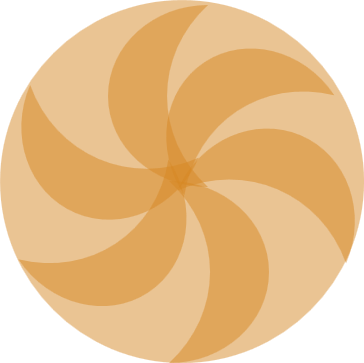

Learn and apply the curvilinear regression workflow for polynomial functions, below. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The    and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction in which you will explore the visualization of a concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

To run the code, you can click the 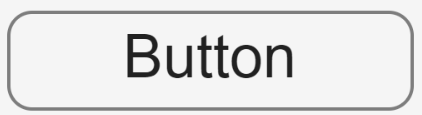 **Button** provided, or you can use [image: Run Section icon] **Run Section** or [image: Run and Advance icon] **Run and Advance** in the Live Editor tab of the tool strip, or the equivalent keyboard commands of Ctrl-Enter to run a section or Ctrl-Shift-Enter to run and advance.

## Notes About this Script  

We will use [Name-Value Arguments](https://www.mathworks.com/help/matlab/matlab_prog/validate-name-value-arguments.html?s_tid=srchtitle_support_results_1_Name-Value%2520arguments) throughout this script such as `DisplayName="Data"`, `Location="best"`. In addition, rather than manually labeling entries on legends, we will use the following format: `legend("show",Location="best")`. In [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), you can practice with Name-Value Arguments in the [Plots](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=9) section. We will also use [dot notation](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html) to access properties of tables. 

In the [Explore Data with MATLAB Plots](https://matlabacademy.mathworks.com/details/explore-data-with-matlab-plots/otmledp) in the [Visualize Vectors](https://matlabacademy.mathworks.com/details/explore-data-with-matlab-plots/otmledp#module=2) section, you can learn more about Name-Value Arguments.

Learn more about dot notation:

-  [Access and Modify Plot Properties ](https://matlabacademy.mathworks.com/details/how-matlab-graphics-work/otmlhgw#module=3)in the Self-Paced Online Course, [How MATLAB Graphics Work](https://matlabacademy.mathworks.com/details/how-matlab-graphics-work/otmlhgw)

- The documentation page [dot notation](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html)

## Fit Polynomial Regression Model

### Generate Polynomial Data

In the code block below, a random number generator is used to create a dataset that follows a third‑order polynomial. The generated data are stored in a table, `T`, with variables labeled `x` and `y`. You can use [dot notation](https://www.mathworks.com/help/matlab/creating_plots/access-and-modify-property-values.html) to extract the variables x and y from the table. 

  **Try**. Click **Generate Data** to generate a synthetic polynomial data set and store it in a table, `T,` with variables x and `y.`

 
T = GenData; % Use function to generate data
head(T) % View top rows of table data and the column labels
x = T.x; % Extract the input variable from the table
y = T.y; % Extract the response variable from the table

### Plot the Data

  **Try**. Make a [scatter](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_support_results_1_scatter) plot of the data by clicking **Plot the Data**.

% Plot original response and fitted polynomial
scatter(x,y,"filled",DisplayName="Data",SeriesIndex=3) % Make a scatter plot of the data
legend("show",Location="Best") % Add a descriptive legend
xlabel("x") % Label x-axis
ylabel("y") % Label y-axis
title("Polynomial Data") % Add a descriptive title
 

### Find and View the Best-Fit for the Polynomial Data

  **Try**. We can use the [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) function in MATLAB to calculate the coefficients ($a_0$ $a_1$, $\dots$, $a_p$) for a regression line, and we can determine the values of the fit using the [`polyval`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/polyval.html) function then click **Evaluate the Polynomial Fit** to calculate the coefficients and evaluate the values of the polynomial function.

  **Tip**. Include [`hold on` ](https://www.mathworks.com/help/matlab/ref/hold.html#d126e768349)at the end of your code to keep the existing plot on the same axes for plotting the predicted values in the next section. 

% Determine 3rd-order polynomial regression model using polyfit
a = polyfit(x,y,3); % 'a' contains coefficients [a3 a2 a1 a0]
% Predict responses from the fitted model
yfit = polyval(a,x);
% Plot fitted polynomial vs. x on top of existing scatter plot
hold on % Retain current plot on axes
plot(x,yfit,LineWidth=1.5,DisplayName="Polynomial Fit",SeriesIndex="none")
legend("show",Location="Best")
box on
hold on % Retain the current plot on axes
 

## Polynomial Model Prediction & Visualization

### Use a Polynomial Regression Model to Predict One Value

We can use the [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) function in MATLAB to predict specific values of the polynomial regression model. In the example code block below, we demonstrate the use of the [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) function.

  **Try**. We use [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) to predict the value for 0.67 and use `scatter` to plot the predicted value marked by a size 60 filled diamond. Set the `DisplayName` in the call to `scatter` for use in the legend then click **Plot the Predicted Value on the Curve**.

  **Tip**. Run the previous section to load the data and create the linear regression model, and include [`hold off`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?searchPort=60962#d126e778590) after plotting the predicted values to stop retaining the current plot and restore the default axes.

% Predict fitted polynomial at x = 0.67
PredictedValue = polyval(a,0.67)
% Mark predicted point on current axes
scatter(0.67,PredictedValue,60,"d","filled",DisplayName="Prediction")
hold off % Release all plots from axes
 

### Use a Polynomial Regression Model to Predict Multiple Values

  **Try**. We can even use [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) to predict the responses for a range of values. Click **Predict Multiple Values** to predict the responses for x-values of -1.6, -0.53, 0.38, and 1.9.

xNew = [-1.6;-0.53;0.38;1.9]; % points to predict
yPredictions = polyval(a,xNew); % evaluate fitted polynomial at these points
disp(table(xNew,yPredictions,VariableNames={'x','yPred'}))
 

### Plot Multiple Predicted Values on Best-Fit Plot

 **Exercise 1.** Modify the code to add the newly predicted values marked by a size 100 "`pentagram"` overlaid on the initial plot using `DisplayName="Additional Predictions"`.

% Rerun code in 'Find and View the Best-Fit for the Polynomial Data' section
scatter(xNew,yPredictions,100,"pentagram","filled",DisplayName="Prediction")
hold off

##  **Application 1. Centrifugal Pump**

Centrifugal pumps are commonly used in chemical process plants to transport liquids through piping networks connecting unit operations. At a fixed rotational speed, the relationship between **pump head** and **volumetric flow rate** is described by the pump characteristic curve, which is often approximated by a **quadratic polynomial** over the normal operating range:


$$H(Q)=a+bQ+cQ^2$$
 

where $H$ is the pump head (m) and Q is the flow rate $(m^3/s)$.

### Load Centrifugal Pump Data

 **Exercise 2a.** Load the data from the function `CenPump` that returns the variable `T`, which is the table of the input variable, `Q`, and `HExp` is the response variable. Display the top rows of table data and the column labels. 

% Create CenPump table: Q, H, HExp (noisy, monotonic)
T = CenPump;
HExp = T.HExp;
Q = T.Q;
% Display first rows to inspect generated pump data
head(T)

### Plot the Data

 **Exercise 2b.** Make a [scatter](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_support_results_1_scatter) plot of `HExp` vs. `Q.`

figure
% Plot original response and fitted polynomial
scatter(Q,HExp,"filled",DisplayName="Data",SeriesIndex=3) % Make a scatter plot of the data
legend("show",Location="Best") % Add a descriptive legend
xlabel("$Q (m^3/s)$",Interpreter="latex") % Label x-axis
ylabel("$HExp (m)$",Interpreter="latex") % Label y-axis
title("Polynomial Data") % Add a descriptive title
box on

### Find and View the Best-Fit for the Polynomial Data

 **Exercise 2c.** Use the [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) function in MATLAB to calculate the coefficients ($a_0$ $a_1$, $\dots$, $a_p$) for a regression line, `HFit`, and determine the values of the fit using [`polyval`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/polyval.html) function. 

  **Tip**. Include [`hold on` ](https://www.mathworks.com/help/matlab/ref/hold.html#d126e768349)at the end of your code to keep the existing plot on the same axes for plotting the predicted values in the next section. 

% Determine 3rd-order polynomial regression model using polyfit
a = polyfit(Q,HExp,3); % 'a' contains coefficients [a0 a1 a2]
% Predict responses from the fitted model
HFit = polyval(a,Q);
% Plot fitted polynomial vs. Q on top of existing scatter plot
hold on % Retain current plot on axes
plot(Q,HFit,LineWidth=1.5,DisplayName="Quadratic Fit",SeriesIndex="none")
legend("show",Location="Best")
box on
hold on % Retain the current plot on axes

### Use a Polynomial Regression Model to Predict One Response

 **Exercise 2d.** Use [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) to predict the value for $0.032m^3/s$ and use `scatter` to plot the predicted value marked by a size 60 filled diamond. Set the `DisplayName` in the call to `scatter` for use in the legend. 

  **Tip**. Run the previous section to load the data and create the linear regression model, and include [`hold off`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?searchPort=60962#d126e778590) after plotting the predicted values to stop retaining the current plot and restore the default axes.

% Evaluate fitted polynomial at x = 0.032 (compute predicted response)
PredictedH = polyval(a,0.032);
% Mark predicted point on plot with a filled diamond marker
scatter(0.032,PredictedH,60,"d","filled",DisplayName="Prediction")
hold off % Release all plots from axes

##  **Application 2. Bioreactor**

[image: Bioreactor cartoon]

Bioreactors are commonly operated at fixed conditions of pH, aeration, and substrate concentration. At a fixed set of these conditions, the **product titer after 24 hours** depends primarily on the **bioreactor temperature**. Over the normal operating range, this relationship can be approximated by a **quadratic polynomial**:


$$P=aT^2+bT+c$$


where

- $P$ is the product titer after 24 h (g/L)

- $T$ is the reactor temperature (°C)

- $a,b,\text{and }c$ are empirical model parameters

### Load Bioreactor Data

  **Try**. Click **Load Data** to load the bioreactor data into the table `Tbio`, which includes the input variable `Temp` and the response variable `Prod`.

% Load bioreactor table and sorted vectors (Temp, Prod)
[Tbio,Temp,Prod] = BioReactorData;
% Display first rows to inspect data
head(Tbio)
 

### Plot the Data

 **Exercise 3a.** Make a [scatter](https://www.mathworks.com/help/matlab/ref/scatter.html?s_tid=srchtitle_support_results_1_scatter) plot of `Prod` vs. Temp`.`

% Plot original response and fitted polynomial
scatter(Temp,Prod,"filled",DisplayName="Data",SeriesIndex=3) % Make a scatter plot of the data
legend("show",Location="Best") % Add a descriptive legend
xlabel("$Temp\ \mathrm{^\circ C}$",Interpreter="latex") % Label x-axis
ylabel("$Product (g/L)$",Interpreter="latex") % Label y-axis
title("Bioreactor Data") % Add a descriptive title
box on
hold on

### Find and View the Best-Fit for the Polynomial Data

 **Exercise 3b.** Use the [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) function in MATLAB to calculate the coefficients ($a_0$ $a_1$, $\dots$, $a_p$) for a regression line, Prod`Fit`, and determine the values of the fit using [`polyval`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/polyval.html) function. 

  **Tip**. Include [`hold on` ](https://www.mathworks.com/help/matlab/ref/hold.html#d126e768349)at the end of your code to keep the existing plot on the same axes for plotting the predicted values in the next section. 

% Determine 2nd-order polynomial regression model
a = polyfit(Temp,Prod,2);   % coefficients [a2 a1 a0]

% Evaluate polynomial
ProdFit = polyval(a,Temp);

% Plot fitted polynomial
plot(Temp,ProdFit,LineWidth=1.5,DisplayName="Quadratic Fit",SeriesIndex="none")

% Show legend
legend("Location","best")

### Use a Polynomial Regression Model to Predict One Response

 **Exercise 3c.** Use [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html?s_tid=srchtitle_support_results_1_polyval) to predict the value for 36.8 $\degree{C}$ and use `scatter` to plot the predicted value marked by a size 60 filled diamond. Set the `DisplayName` in the call to `scatter` for use in the legend. 

  **Tip**. Run the previous section to load the data and create the linear regression model, and include [`hold off`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?searchPort=60962#d126e778590) after plotting the predicted values to stop retaining the current plot and restore the default axes.

% Evaluate fitted polynomial at 36.8 and plot the prediction
PredictedH = polyval(a,36.8);
scatter(36.8,PredictedH,60,"d","filled",DisplayName="Prediction")
hold off % Release all plots from axes

## Further Exploration

Model your own [Centrifugal Pump](https://www.mathworks.com/help/hydro/ref/centrifugalpumpil.html) in Simscape™.

[⇦ Return to Curvilinear Regression](matlab:open('./CurvilinearRegressionSoln.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

function T = GenData
% Generate sample data for a 3rd-order polynomial with noise and return as a table
x = linspace(-2,2,25)'; % predictor
% True 3rd-order polynomial coefficients (from highest to lowest power)
trueCoeff = [2 -1 0.5 0.2]; % y = 2*x^3 - x^2 + 0.5*x + 0.2
y = polyval(trueCoeff,x) + 0.5*randn(size(x)); % responses with noise
T = table(x,y,VariableNames={'x','y'});
end

function [Tbio,Temp,Prod] = BioReactorData
S = load('Bioreactor.mat','Temp','Prod'); % load variables into struct
Tbio = table(S.Temp(:),S.Prod(:),VariableNames={'Temp','Prod'}); % create table
Tbio = sortrows(Tbio,'Temp'); % sort table by Temp
Temp = Tbio.Temp; % overwrite Temp with sorted data
Prod = Tbio.Prod; % overwrite Prod with sorted data
end

function T = CenPump %#ok<*DEFNU>
% Quadratic pump coefficients
a = 45; % m
b = 450; % m / (m^3/s)
c = 5000; % m / (m^3/s)^2
% Flow vector
Qmax = 0.06;
Q = (0:0.005:Qmax)';
% True quadratic curve
H = a - b*Q - c*Q.^2;
% Generate NEW random noise every run
rng shuffle
% Noisy experimental data
HExp = H + randn(size(H));
% Optional: enforce physically realistic monotonic decrease
HExp = cummin(HExp);
% Return table
T = table(Q,H,HExp);
end